# Full Data Processing Pipeline

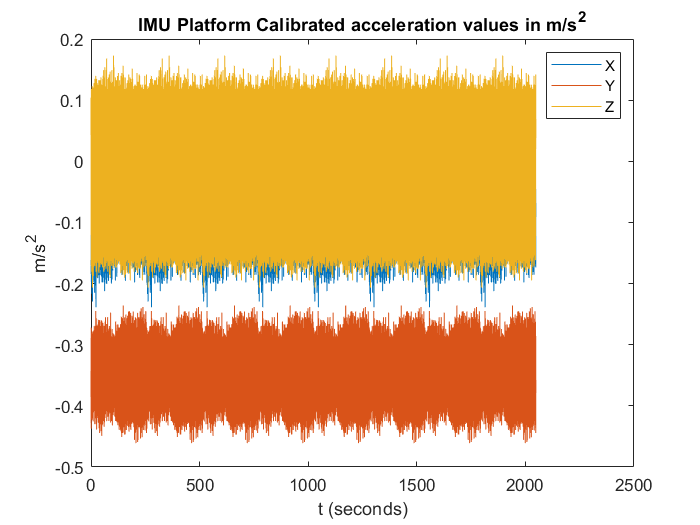

% Author: Michael Noyce
% This data processing pipeline is implemented in the STM32L4
% on the UCT SHARC Buoy, this MATLAB program is the golden measure 
% for the software implementation

% Stage 0: Data Input
% Pre-processing of raw IMU Data
IMUData = readtable('05Hz_20mm_reg.csv');
rawXAcc = IMUData{:, 2}(20000:45600-1);
rawYAcc = IMUData{:, 3}(20000:45600-1);
rawZAcc = IMUData{:, 4}(20000:45600-1);
rawRoll = IMUData{:, 5}(20000:45600-1);
rawPitch = IMUData{:, 6}(20000:45600-1);
rawYaw = IMUData{:, 7}(20000:45600-1);

rawXAcc = cat(1, rawXAcc, rawXAcc, rawXAcc, rawXAcc, rawXAcc, rawXAcc, rawXAcc, rawXAcc);
rawYAcc = cat(1, rawYAcc, rawYAcc, rawYAcc, rawYAcc, rawYAcc, rawYAcc, rawYAcc, rawYAcc);
rawZAcc = cat(1, rawZAcc, rawZAcc, rawZAcc, rawZAcc, rawZAcc, rawZAcc, rawZAcc, rawZAcc);
rawRoll = cat(1, rawRoll, rawRoll, rawRoll, rawRoll, rawRoll, rawRoll, rawRoll, rawRoll);
rawPitch = cat(1, rawPitch, rawPitch, rawPitch, rawPitch, rawPitch, rawPitch, rawPitch, rawPitch);
%rawYaw = cat(1, rawYaw, rawYaw, rawYaw, rawYaw, rawYaw, rawYaw, rawYaw, rawYaw);

Fs = 100;             % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = height(rawXAcc);  % Length of signal
t = (0:N-1)*T;        % Time vector
d_sample_ratio_1 = 10;
d_sample_ratio_2 = 5; 
d_sample_ratio = d_sample_ratio_1*d_sample_ratio_2; 
% Stage 1: IMU Calibration 
% Using the calibration values determined for the IMU, 
% convert raw readings to calibrated acceleration and orientation values

[accXCal, accYCal, accZCal, rollCal, pitchCal, yawCal] = calibrateICM20689(rawXAcc, rawYAcc, rawZAcc, rawRoll, rawPitch, rawYaw);

figure();
plot(t, accXCal, t, accYCal, t, accZCal);
title('IMU Platform Calibrated acceleration values in m/s^2')
legend("X", "Y", "Z")
xlabel('t (seconds)')
ylabel('m/s^2')

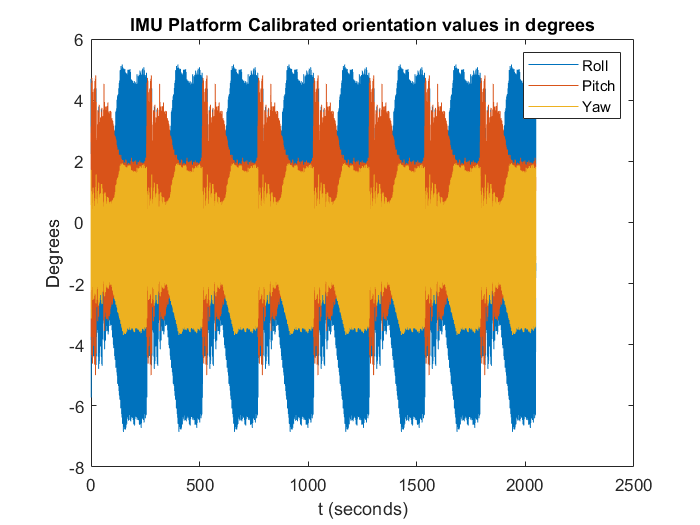


figure();
plot(t, rollCal, t, pitchCal, t, yawCal);
title('IMU Platform Calibrated orientation values in degrees')
legend("Roll", "Pitch", "Yaw")
xlabel('t (seconds)')
ylabel('Degrees')

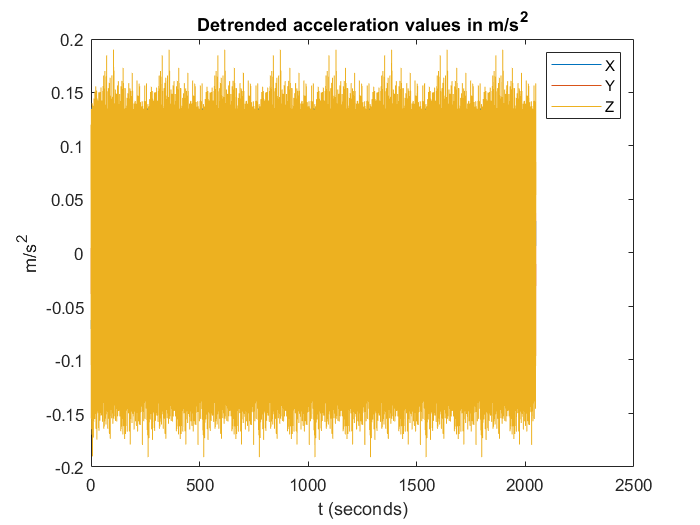



%Stage 2: Detrend IMU Time Series
%Detrend the IMU Time Series Values 

accX = embeddedDetrend(accXCal);
accY = embeddedDetrend(accYCal);
accZ = embeddedDetrend(accZCal);
roll = embeddedDetrend(rollCal);
pitch = embeddedDetrend(pitchCal);
yaw = embeddedDetrend(yawCal);

figure();
plot(t, accX, t, accY, t, accZ);
title('Detrended acceleration values in m/s^2')
legend("X", "Y", "Z")
xlabel('t (seconds)')
ylabel('m/s^2')

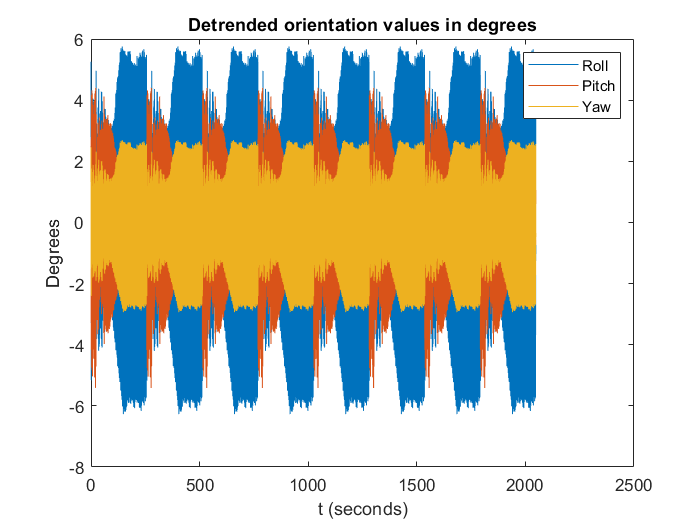


figure();
plot(t, roll, t, pitch, t, yaw);
title('Detrended orientation values in degrees')
legend("Roll", "Pitch", "Yaw")
xlabel('t (seconds)')
ylabel('Degrees')


%Stage 3: Correct to vertical
%Use detrended and calibrated IMU values to determine true vertical motion

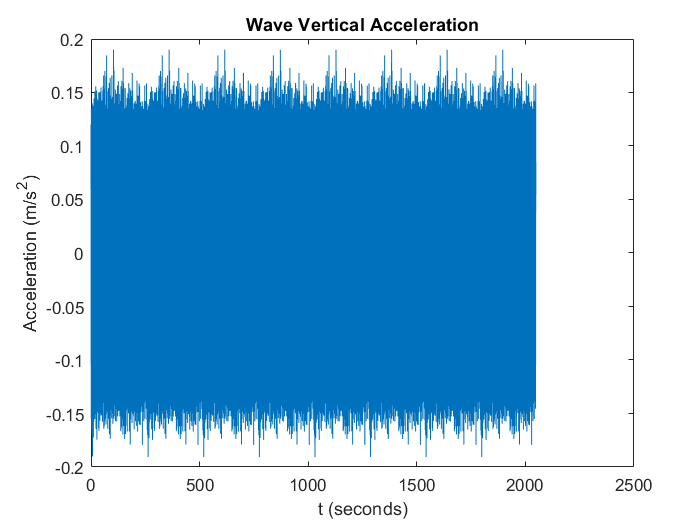

%waveVertAcc = vertCorrect(accX, accY, accZ, roll, pitch);
waveVertAcc = accZ;

figure();
plot(t, waveVertAcc);
title('Wave Vertical Acceleration')
xlabel('t (seconds)')
ylabel('Acceleration (m/s^2)')

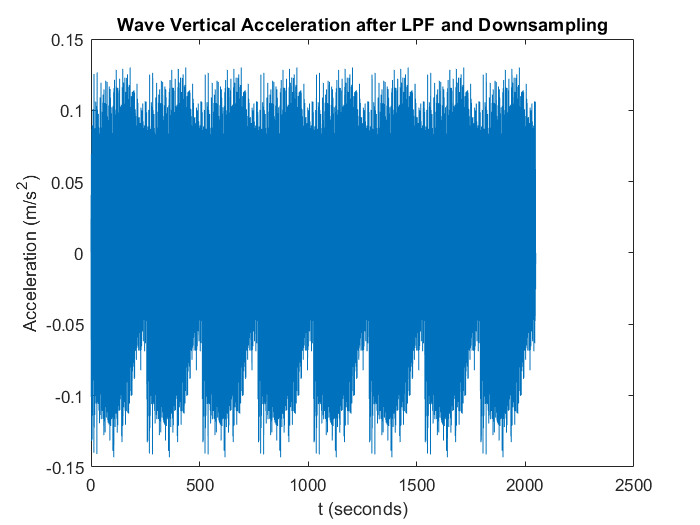


%Stage 4: LPF and decimation (prevents Harmonics in stage 5!) 
[t, waveVertAcc] = embeddedLowpass(t, waveVertAcc, d_sample_ratio_1, d_sample_ratio_2);

figure();
plot(t, waveVertAcc);
title('Wave Vertical Acceleration after LPF and Downsampling')
xlabel('t (seconds)')
ylabel('Acceleration (m/s^2)')

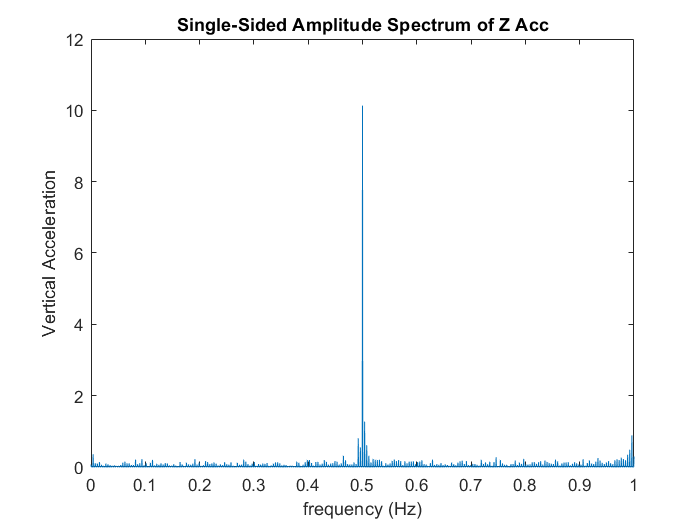


%Stage 5: Frequency Transform
[f, waveAmplitudeFFTSingleSide, waveAmplitudeFFTDoubleSide] = embeddedFFT(waveVertAcc, Fs, N, d_sample_ratio);

plot(f, waveAmplitudeFFTSingleSide) 
title('Single-Sided Amplitude Spectrum of Z Acc')
xlabel('frequency (Hz)')
ylabel('Vertical Acceleration')

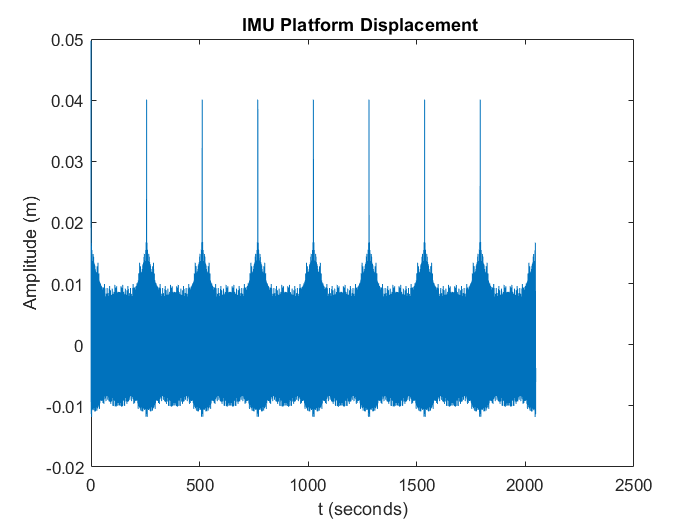


%Stage 6
% Double integration and HPF
%%Wave Height Calculation
[t_trunc, waveAmplitude] = HPFDoubleIntegration(t, f, Fs, d_sample_ratio, waveAmplitudeFFTSingleSide, waveAmplitudeFFTDoubleSide);


plot(t_trunc, real(waveAmplitude))
title('IMU Platform Displacement ')
xlabel('t (seconds)')
ylabel('Amplitude (m)')

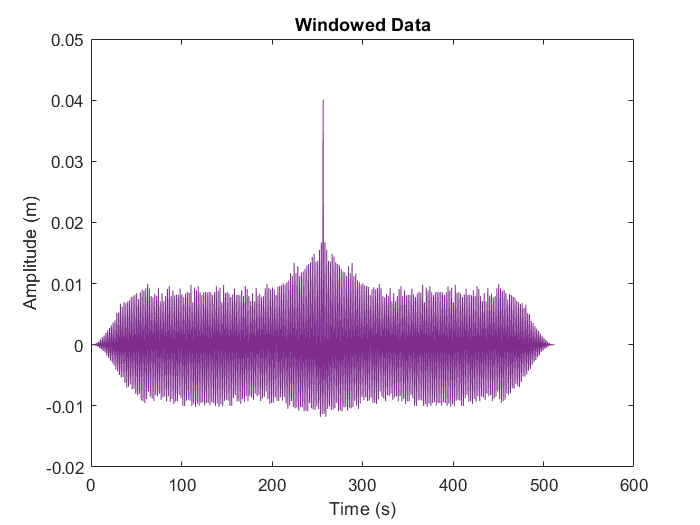


%Window Time Series
pcosineWindow = tukeywin(1024, 0.25);

%Stage 7: Window and Overlap Time Series 
%NB replace with double for loops!
fullTimeSeries = zeros(4096, 1);
fullTimeSeries = real(waveAmplitude);
testInput = fullTimeSeries(1, :); 

% Windowing in input signal
NUMBER_OF_WINDOWS = 4;
WINDOW_LENGTH = 1024; 
FFT_LENGTH = WINDOW_LENGTH/2; 
windows = zeros(NUMBER_OF_WINDOWS, WINDOW_LENGTH);

for i = 1 : NUMBER_OF_WINDOWS
        for  j = 1 : WINDOW_LENGTH
           windows(i, j) = testInput(j + i*(WINDOW_LENGTH /2))*pcosineWindow(j);
        end
end

t_trunc = (1:1024)*0.5;

plot(t_trunc, windows(1,:), t_trunc, windows(2,:), t_trunc, windows(3,:), t_trunc, windows(4,:));
title('Windowed Data')
xlabel('Time (s)')
ylabel('Amplitude (m)'); 

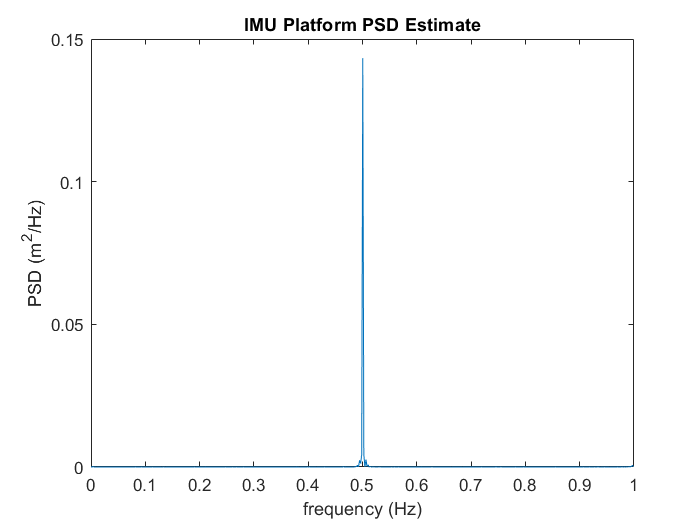




%Stage 8: FFT Windowed Segments

windowFFTMagnitude = zeros(NUMBER_OF_WINDOWS, FFT_LENGTH);
windowFFT = zeros(NUMBER_OF_WINDOWS, FFT_LENGTH+1);
Fs = Fs/d_sample_ratio;
testOutput = zeros(1, FFT_LENGTH);

for i = 1 : NUMBER_OF_WINDOWS 
  [f, windowFFT(i, :), ~] = embeddedFFT(windows(i, :), Fs, WINDOW_LENGTH-1, 1);
  windowFFTMagnitude(i, :) = abs(windowFFT(i, 1:512));
end 

%Stage 9: Periodogram estimate

for i = 1 : NUMBER_OF_WINDOWS
    for j = 1  : FFT_LENGTH
    windowFFTMagnitude(i, j) =  (windowFFTMagnitude(i, j) * windowFFTMagnitude(i, j))*(Fs*FFT_LENGTH); 
    end
end

%Stage 10: Averaging 
for i = 1 : FFT_LENGTH
    
    temp = 0;
   
    for j = 1  : NUMBER_OF_WINDOWS
    temp =  windowFFTMagnitude(j , i) + windowFFTMagnitude(j , i);
    end
    
    
    testOutput(i) = temp./NUMBER_OF_WINDOWS;
   
end

plot(f, testOutput);
title('IMU Platform PSD Estimate')
xlabel('frequency (Hz)')
ylabel('PSD (m^2/Hz)')



%Stage 11: Extraction of key parameters
%Numerical Integration to calculate spectral moments using Newton Cotes
%method - could use another method

%As the spectrum graph is built using linear interpolation, a composite
%trapezoidal rule will be used for numerical integration.
%Spectrum function E(f)=mW
%total number of points
m=length(testOutput);
%number of subintervals
m=m-1;
%length of the subinterval
Ax=(f(m+1)-f(1))/m;
%Integral I1 m0=int{E(f)df} I1
s=0;
for i=2:m
 s=s+testOutput(i); %sum(2,m) f(xi)
end
m0=0.5*Ax*(testOutput(1)+2*s +testOutput(m+1));
%Integral I2 m1=int{f*E(f)df} I2
s=0;
%f=f*E(f)=f*mW
for i=2:m
 s=s+f(i)*testOutput(i);
end
m1=0.5*Ax*(f(1)*testOutput(1)+2*s+f(m+1)*testOutput(m+1));
%Integral I3 m2=int{f^2*E(f)df} I3
s=0;
for i=2:m
 s=s+(f(i))^2*testOutput(i);
end
m2=0.5*Ax*((f(1))^2*testOutput(1)+2*s+(f(m+1))^2*testOutput(m+1));
%Integral I4 m_1=int{f^(-1)*E(f)df} I4
s=0;
for i=3:m
 s=s+testOutput(i)/f(i);
end
m_1=0.5*Ax*(1/f(2)*testOutput(2)+2*s+1/f(m+1)*testOutput(m+1));
%Note: f(1)=0 and so it is expluded. The integral is not fully computed.
%There is a mistake there!
%Spectrum analysis output
%Significant wave height
%Hm0=4*sqrt(int{E(f)df})
Hm0=4*sqrt(m0);
%Mean spectral wave period
%Tm01=(int{E(f)df}/(f*int{E(f)df}))
Tm01=m0/m1;
%Peak wave period
[M,i]=max(testOutput);
fm=f(i);
Tp=1/fm;
%Mean zero-crossing period
T0=sqrt(m0/m2);
%Mean spectral wave period Tm-1,0 with a higher weight of the longer waves
Tm_10=m_1/m0;
%Remember that one point has been ommited to compute Tm_10. I am not sure
%if it does not affect the result!
%Root Mean Square Wave height
Hrms=sqrt(2)/2*Hm0;

%Done!